# BV lab 3 by Patrick Spaans (11268476) & Bram Otten (10992456)

- The few theory questions are answered in here.

- Deadline is Wednesday 02-05.

- Images in './Images/', functions from this folder.

- Book section 8.3 (page 139 of the PDF).

- Question order will be as it is in the exercise.

- X-values are columns, Y-values are rows.

## 2 - Finding Lines using the Hough Transform

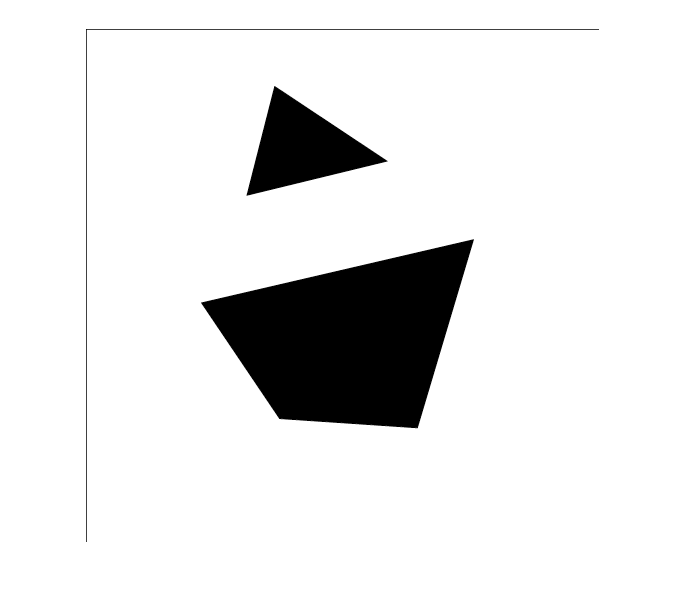

shapes = rgb2gray(im2double(imread('Images/shapes.png'))); 
imshow(shapes);

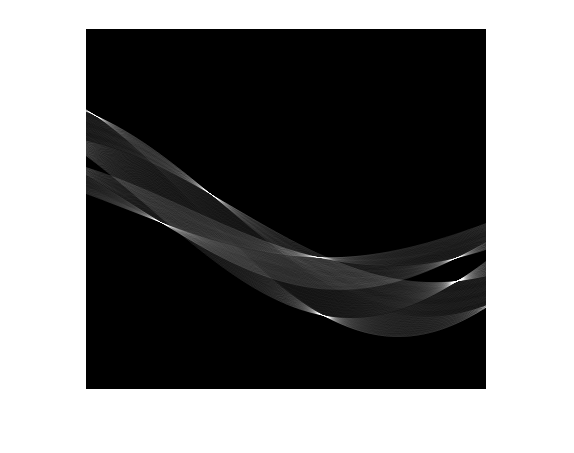

% Named it myHough.m to not overwrite the built-in hough function.
Thresh = .8; nrho = 360; ntheta = 400;
houghShapes = myHough(shapes, Thresh, nrho, ntheta);
imshow(3 * houghShapes);  % corresponds to sample figure.

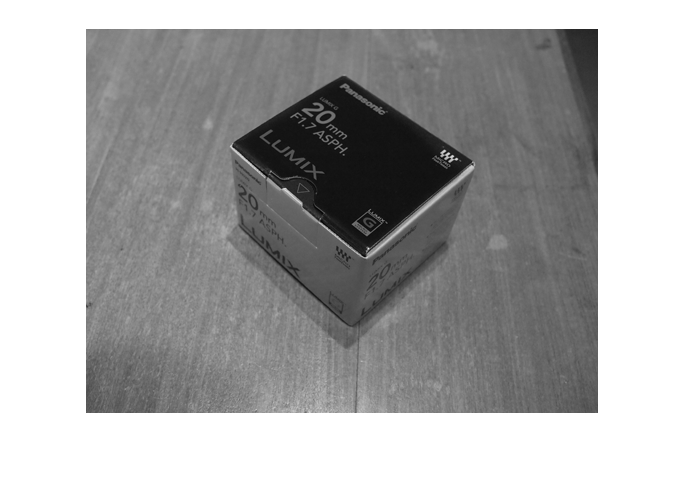

box= rgb2gray(im2double(imread('Images/box.png')));
imshow(box);

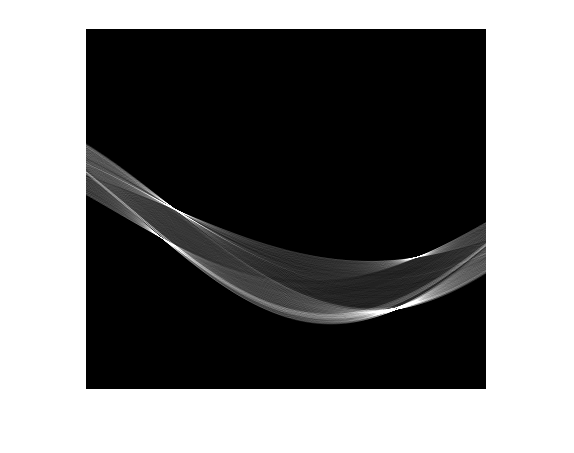

hBox = myHough(box, Thresh, nrho, ntheta);
imshow(3 * hBox);

**Theory 1**

The point-to-sine Hough transform in the book is $x \cos \theta + y \sin \theta = \rho$. The one used here is $x \sin \theta - y \cos \theta = \rho$. Compared to normal x,y axes, MATLAB's are swapped, and then the new y direction is flipped as well (it undergoes a sign change). Keeping this in mind, the resulting $\rho$ should be the same. So there is no geometric difference, this change is just to handle MATLAB.

**Theory 2**

The given range of $\theta$ is $0 \leq \theta < \pi$, which in degrees means $\theta$ can be at most 180 degrees. If $\rho$ could only be positive, that would mean only lines that cross the y-axis above the origin could be made in the $(\rho, \theta)$ parameter space. That's not wanted, so $\rho$ can be negative. If $\theta$ could be $3\pi/2$ or something like that (have a greater range), those lines crossing the y-axis below the origin become possible as well.

## 3 - Finding the Lines as Local Maxima

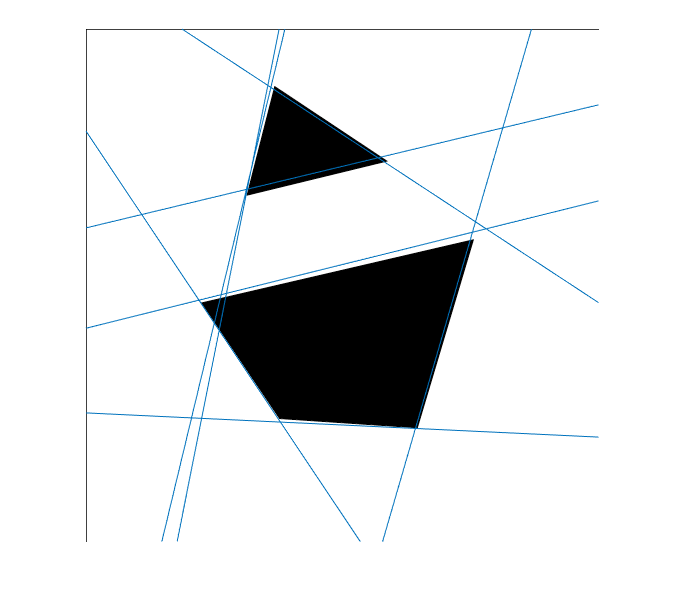

shapesLines = 	1.0e+05 *

   -0.0002    0.0051   -1.9719
   -0.0034    0.0051    0.3225
   -0.0051    0.0034   -0.3491
   -0.0051   -0.0010    0.9936
   -0.0051   -0.0012    1.0235
   -0.0051   -0.0015    2.2887
    0.0012    0.0051   -1.0235
    0.0013    0.0051   -1.5382


thresh = .42;
shapesLines = myHoughlines(shapes, houghShapes, thresh)

## 5 - Optimal Line Estimation

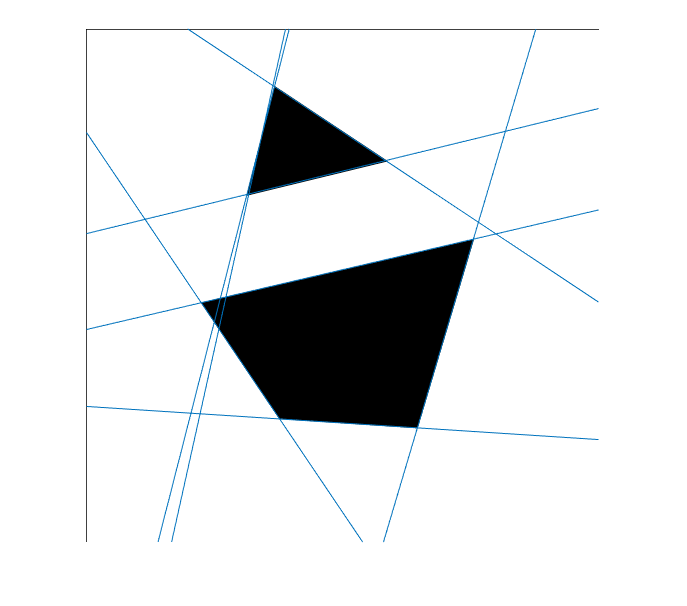

% Get an image containing only the edges of shapes and use find() to 
% get all the relevant edge points
shapesEdges = edge(shapes, 'Canny', Thresh);
[x, y] = find(shapesEdges);
shapePoints = [y, x];
epsilon = 7;
imshow(shapes);
hold on;
% For all lines, find the non-zero points with a distance less epsilon 
% and use those to calculate a new line. 
% Using this new line, calculate to points and plot the line between them.
for oldL = shapesLines'
    points = points_of_line(shapePoints, oldL, epsilon);
    if length(points) > 2
        l = line_through_points(points);
        x1 = 1;
        x2 = size(shapes, 2);
        y1 = (x1 * l(1) + l(3))/-l(2);
        y2 = (x2 * l(1) + l(3))/-l(2);
        line([x1, x2], [y1, y2]);
    end
end
hold off;

## 6 - Using the Lines

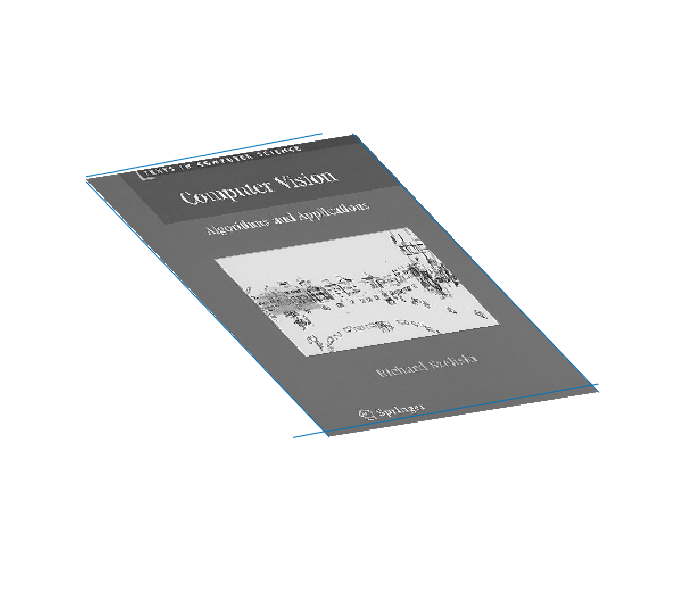

% Calculate the lines around szeliski.png using MyHoughlines
szeliski = rgb2gray(im2double(imread('Images/szeliski.png'))); 
Thresh = .99; nrho = 360; ntheta = 400;
hSzeliski = myHough(szeliski, Thresh, nrho, ntheta);
thresh = .5;
szeliskiLines = myHoughlines(szeliski, hSzeliski, thresh);

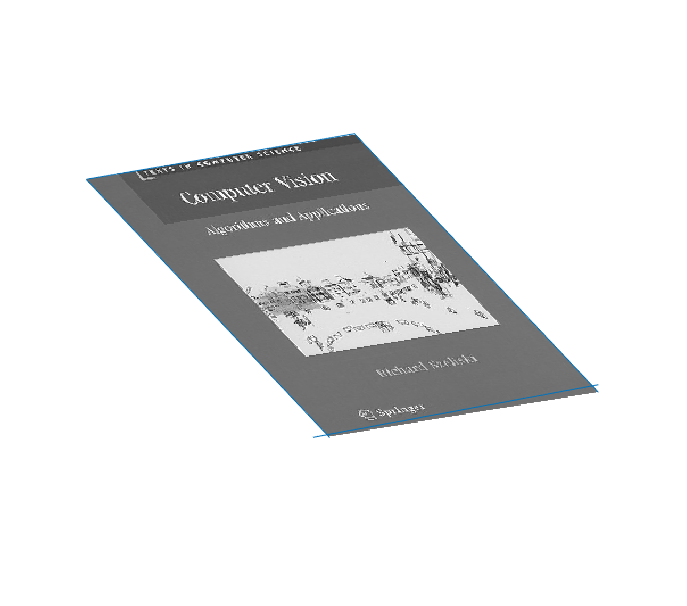

% Get an image containing only the edges of szeliski and use 
% find() to get all the relevant edge points
szeliskiEdges = edge(szeliski, 'Canny', Thresh);
[x, y] = find(szeliskiEdges);
szeliskiPoints = [y, x];

epsilon = 5;
imshow(szeliski);
hold on;
lines = [];
i = 1;
% For all lines, find the non-zero points with a distance less 
% epsilon and use those to calculate a new line. 
% Using this new line, calculate to points and plot the line between 
% them. Store all lines in a list.
for oldL = szeliskiLines'
    points = points_of_line(szeliskiPoints, oldL, epsilon);
    if length(points) > 2
        l = line_through_points(points);
        lines(i, :) = l;
        i = i + 1;
        x1 = 1;
        x2 = size(szeliski, 2);
        y1 = (x1 * l(1) + l(3))/-l(2);
        y2 = (x2 * l(1) + l(3))/-l(2);
        line([x1, x2], [y1, y2]);
    end
end
hold off;

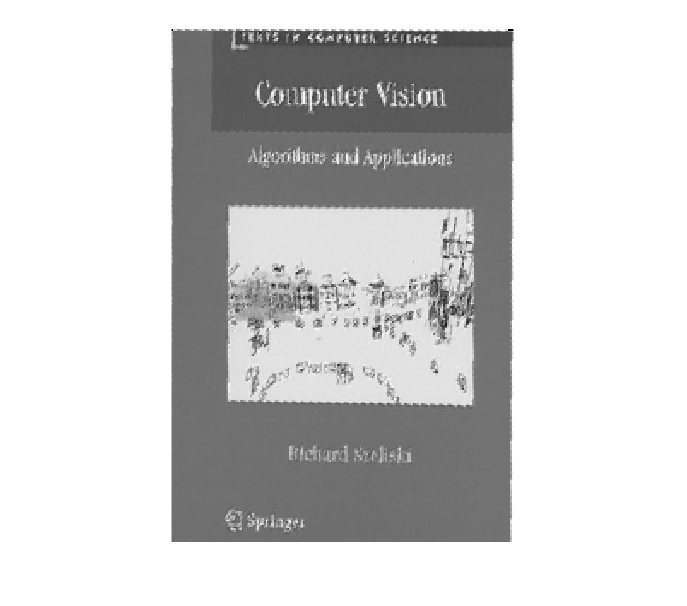

% Get all the corner points of the image by taking the 
% cross products of all the lines and selecting the relevant ones.
corners = getcorners(lines);

% State which line is what corner of the picture, 
% which is required for myProjection.
topleft = corners(1, :);
topright = corners(3, :);
bottomright = corners(4, :);
bottomleft = corners(2, :);
corners = [topleft; topright; bottomright; bottomleft];
corners = [corners(:, 2), corners(:, 1)];
projection = myProjection(szeliski, corners, 300, 200, 'linear');
imshow(projection);

**The intersection of 2D lines is taking the cross product of their homogeneous representatives**

Since taking the cross product of two lines means finding a line that is perpendicular to both, it makes sense that this is the intersection. The only line perpendicular to both these lines, is the line that stands on top of their intersection point, since the line has to be perpendicular to both, it has to intersect both lines at the same point, otherwise the angle wouldn't be the same. This is proven by the code above, since taking the cross product is used in order to find the intersection point.

**The sine of the angle between two lines is proportional to the the homogeneous weight of the vector representing the intersection point**

% Finding the eqation for line 1 and line 3, their intersection is 
% the topleft point.
l = lines(1, :);
x1 = 1;
x2 = size(szeliski, 2);
y1 = (x1 * l(1) + l(3))/-l(2);
y2 = (x2 * l(1) + l(3))/-l(2);
a1 = (y2 - y1) / (x2 - x1);
b1 = y1 - (x1 * a1);

l2 = lines(3, :);
x1 = 1;
x2 = size(szeliski, 2);
y1 = (x1 * l2(1) + l2(3))/-l2(2);
y2 = (x2 * l2(1) + l2(3))/-l2(2);
a2 = (y2 - y1) / (x2 - x1);
b2 = y1 - (x1 * a2);

% Calculating the sine of the angle
sin(atan((a2 - a1)/(1+a2*a1)))

ans = -0.8321

cross(l, l2)

ans =     0.5092   33.8120    0.8321


The weight of the homogeneous coordinates (the third value of the cross product above) is the same value as the sine of the angle, except that it is negative. Since the only difference is the sign, it is proportional, and the weight = -sin(angle between two lines).

**The cross product of two 2D points, p1 and p2, is the line that connects them.**

We have already made use of this before, which proves this, but we will prove it again: 

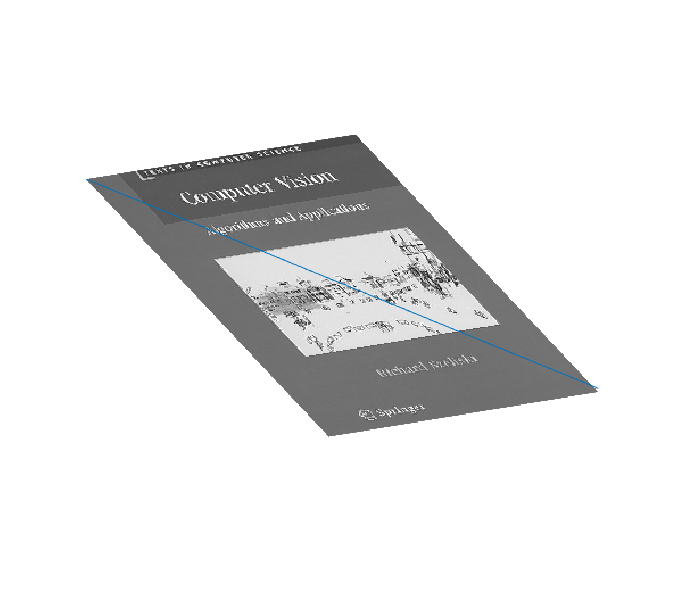

% Calculate the cross product to get the line parameters. Using these, 
% we can calculate two points and draw a line between them.
l = cross([topleft, 1], [bottomright, 1]);
x1 = 1;
x2 = size(szeliski, 2);
y1 = (x1 * l(1) + l(3))/-l(2);
y2 = (x2 * l(1) + l(3))/-l(2);
imshow(szeliski);
hold on;
plot([x1, x2], [y1, y2]);
hold off;

The cross product of the topleft corner and the bottomright corner results in homogeneous line parameters of the line between them. These parameters can then be used to calculate the Y values for given values of X, which will be a point on the line that intersects both of the corners.

The homogeneous weight is an extra dimension to the line vector, which means that it is now a projection vector, used for projective geometry. This extra dimension allows for perspective changes in images. 

% The other method of estimating lines: immediately, using the four lines.

% l' x = 0 = ((M-1)' l)' y. Can then consider that ((M-1)' l)' thing the new lines. 
% Then I think it's for-for'ing through the wanted y coordinates and picking them from the
% original image. 

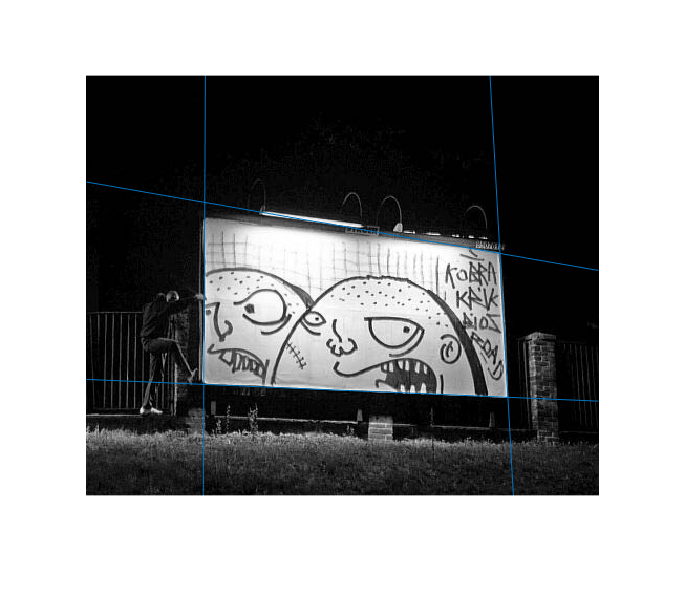

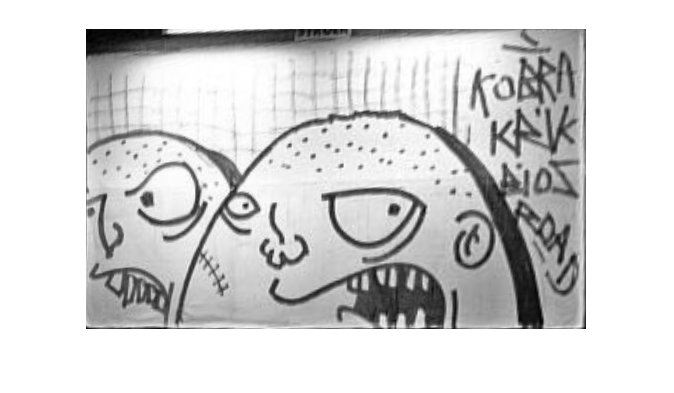

Thresh = .9; thresh = .45; epsilon = 5; order = [4,3,1,2];
doEverything('Images/billboard.png', Thresh, thresh, epsilon, order);

% So the billboard kind of works. Its upper border isn't nice but maybe that's
% because the lightbulb makes it a not-so-nice edge. 

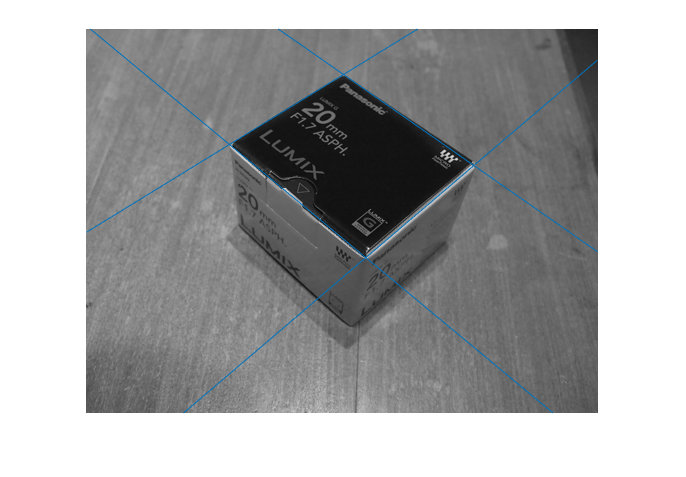

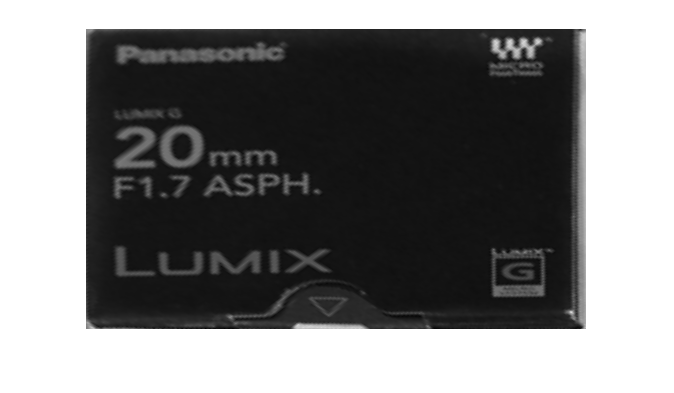

Thresh = .8; thresh = .6; epsilon = 8; order=[2,1,3,4];
doEverything('Images/box.png', Thresh, thresh, epsilon, order);

% This box looks better, at least if we try to project. The lines made by 
% the other sides are harder to detect, again this may be because of the light.